clc; clear; close all;


% part a
epsilon_over_D = [5e-4];
Re_values = [1e5];
friction_factor = modified_secant_method(epsilon_over_D, Re_values(1), 0.01)

friction_factor = 0.0203

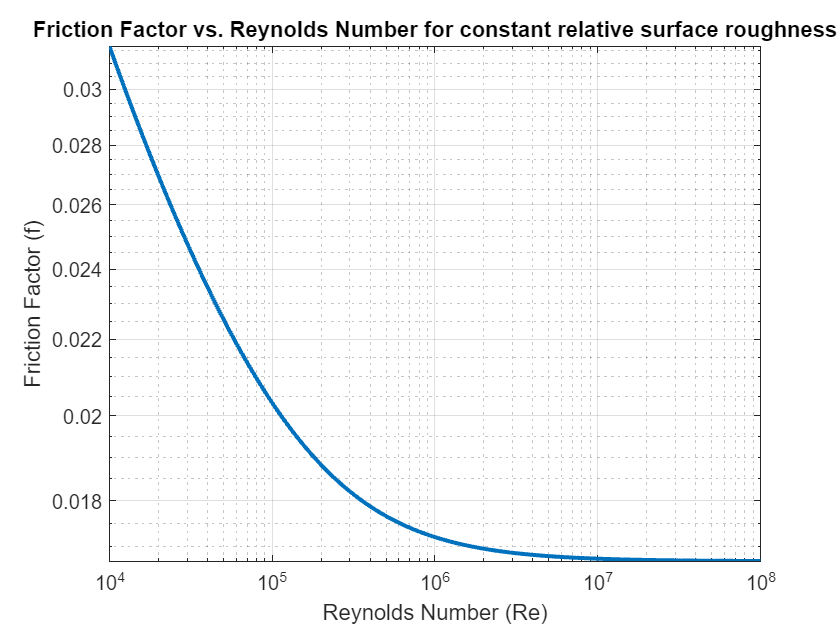

% part b
Re_values = logspace(4, 8, 100);
epsilon_over_D = [5e-4];

friction_factors = zeros(size(Re_values));

for i = 1:length(Re_values)
    friction_factors(i) = modified_secant_method(epsilon_over_D, Re_values(i), 0.01);
end

figure;
loglog(Re_values, friction_factors, 'LineWidth', 2);
xlabel('Reynolds Number (Re)');
ylabel('Friction Factor (f)');
title('Friction Factor vs. Reynolds Number for constant relative surface roughness');
grid on;

% part c

% Re_values = logspace(4, 8, 100)
Re_values = 10^3:100:10^8

Re_values =         1000        1100        1200        1300        1400        1500        1600        1700        1800        1900        2000        2100        2200        2300        2400        2500        2600        2700        2800        2900        3000        3100        3200        3300        3400        3500        3600        3700        3800        3900        4000        4100        4200        4300        4400        4500        4600        4700        4800        4900        5000        5100        5200        5300        5400        5500        5600        5700        5800        5900


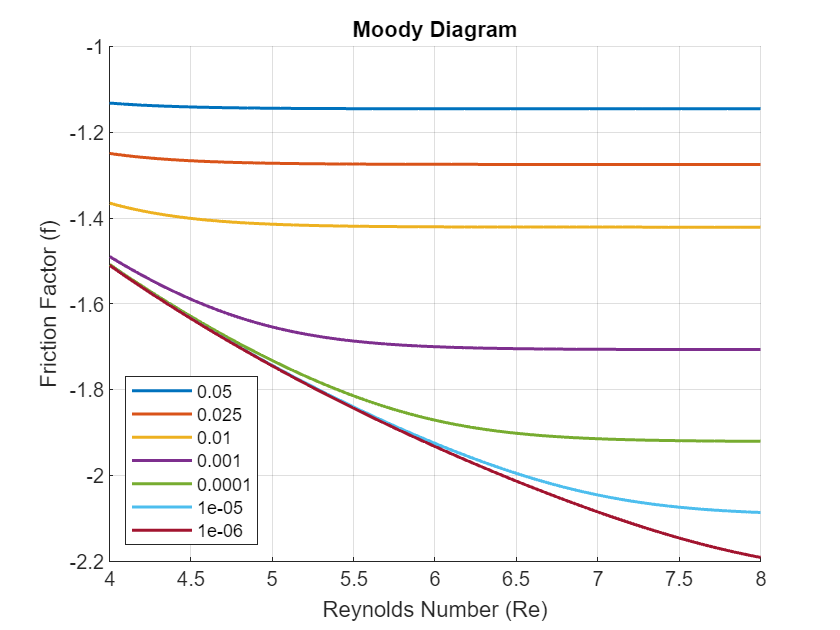

epsilon_over_D = [0.05, 0.025, 0.01, 1e-3, 1e-4, 1e-5, 1e-6];
% epsilon_over_D = [0.05, 0.04, 0.03, 0.02, 0.015, ...
%     0.01, 0.005, 0.002, 0.001, 5e-4, 2e-4,1e-4,5e-5,1e-5,5e-6,1e-6];

friction_factors = zeros(size(Re_values));

figure;
hold on;
for i = 1:length(epsilon_over_D)
    Re_values = logspace(4, 8, 100); % Generate Reynolds number values
    friction_factors = zeros(size(Re_values));
    for j = 1:length(Re_values)
        [friction_factors(j), ~] = modified_secant_method(epsilon_over_D(i), Re_values(j), 0.01);
    end
    loglog(log10(Re_values), log10(friction_factors), 'LineWidth', 1.5);
end

xlabel('Reynolds Number (Re)');
ylabel('Friction Factor (f)');
title('Moody Diagram');
legend(string(epsilon_over_D), 'Location', 'southwest');
grid on;
hold off;

function [friction_factor, iterations] = modified_secant_method(epsilon_D, Re, initial_guess)
    tolerance = 1e-6;
    max_iterations = 100;

    % Define the function for which we want to find the root
    f = @(f) -2*log10(epsilon_D/3.7 + 2.51/(Re*sqrt(f))) - 1/sqrt(f);

    % Initialize variables
    x0 = initial_guess;
    x1 = x0 + 0.01; % Perturb the initial guess slightly
    iterations = 0;

    % Perform the modified secant method
    while abs(x1 - x0) > tolerance && iterations < max_iterations
        x_temp = x1;
        x1 = x1 - f(x1)*(x1 - x0)/(f(x1) - f(x0));
        x0 = x_temp;
        iterations = iterations + 1;
    end

    % Output the results
    friction_factor = x1;
end

